# Data preparation: cleaning

The data in "biopsies_raw.csv" has not been cleaned:

clear all;
data = readtable('biopsies_raw.csv')

data = 570×32 table
        id          diagnosis      radius_mean    texture_mean    perimeter_mean    area_mean    smoothness_mean    compactness_mean    concavity_mean    concave_points_mean    symmetry_mean    fractal_dimension_mean    radius_se    texture_se    perimeter_se    area_se    smoothness_se    compactness_se    concavity_se    concave_points_se    symmetry_se    fractal_dimension_se    radius_worst    texture_worst    perimeter_worst    area_worst    smoothness_worst    compactness_worst    conc

Clean the data and split it ready for training and testing a classifier.

Marks are available for:

- Appropriately addressing: duplicated examples; irrelevant features; missing values [5 marks]

- Identifying and removing the extreme outlier for the "smoothness_mean" feature [3 marks]

- Splitting the data up into an appropriately named training dataset and testing dataset [8 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

summary(data) % radius_mean: NumMissing = 1 (1 cell value in radius_mean column is missing)


Variables:

    id: 570×1 double

        Values:

            Min             8670
            Median    9.0616e+05
            Max       9.1132e+08

    diagnosis: 570×1 cell array of character vectors

    radius_mean: 570×1 double

        Values:

            Min               6.981    
            Median            13.34    
            Max               28.11    
            NumMissing        1        

    texture_mean: 570×1 double

        Values:

            Min             9.71    
            Median        18.835    
            Max            39.28    

    perimeter_mean: 570×1 double

        Values:

            Min            43.79      
            Median         86.21      
            Max            188.5      

    area_mean: 570×1 double

        Values:

            Min          143.5   
            Median      548.75   
            Max           2501   

    

[order, index] = sortrows(data(:, 'radius_mean')) % order column get index of empty cell (254)

order = 570×1 table
    radius_mean
    ___________

       6.981   
       7.691   
       7.729   
        7.76   
       8.196   
       8.219   
       8.571   
       8.597   
       8.598   
       8.618   
       8.671   
       8.726   
       8.734   
       8.878   
       8.888   
        8.95   


index =    102
   541
   540
   570
    47
   152
   527
   315
    62
    60


data(254, :) = []; % delete the row of the cell with missing data

[~, dindex] = sortrows(data(:, 'id')) % 569 total examples

dindex =    132
   287
   291
   403
    48
    96
    97
   109
   112
   113


[~, uindex] = unique(data(:, 'id')) % 568 unique examples

uindex =    132
   287
   291
   403
    48
    96
    97
   109
   112
   113


dup_rows = setdiff(dindex, uindex) % shows row index in dindex not in uindex

dup_rows = 468

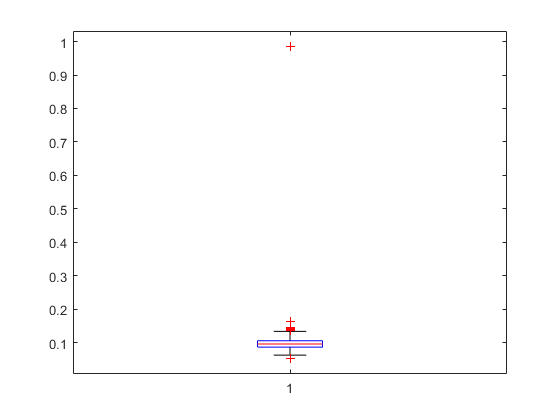

data(dup_rows, :) = []; % delete duplicate row

data(:, 'id') = []; % delete irrelevant columns (id feature)

boxplot(data.smoothness_mean) % boxplot of feature

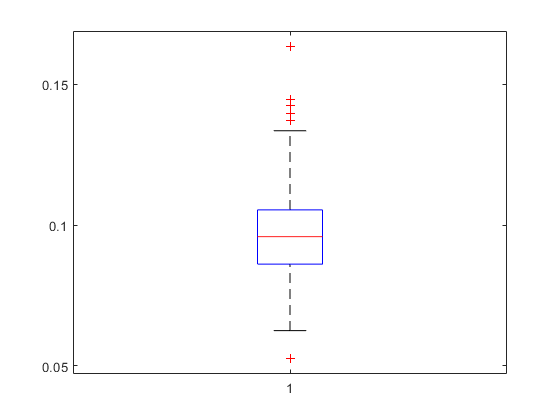

data(159, :) = []; % delete outlier row found using data cursor in figure window
boxplot(data.smoothness_mean) % boxplot of feature


nTest = round(0.20 * size(data,1)) % calculates 20% of data for testing 

nTest = 113

rng(1) % re-seed rng number
data_shuffled = data(randperm(size(data,1)), :); % shuffles all data
data_test = data_shuffled(1:1:nTest, :); % assigns 20% to testing data
data_train = data_shuffled(nTest+1:1:end, :); % assigns 80% to training data

test_labels = categorical(data_test{:,'diagnosis'}); % gets the labels from the testing data
test_examples = data_test; % copies the testing data into the test examples
test_examples(:,'diagnosis') = []; % deletes the diagnosis column from test examples

train_labels = categorical(data_train{:,'diagnosis'}); % gets the labels from the training data
train_examples = data_train; % copies the training data into the train examples
train_examples(:,'diagnosis') = []; % deletes the diagnosis column from train examples


